clear; clc;
cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/Gz.mat
load ../data/ppPoles.mat

Kd = [sysDT.C; sysDT.C*sysDT.A; sysDT.C*sysDT.A^2; sysDT.C*sysDT.A^3]

Kd = 1.0e+06 *

         0         0    0.0002    1.0000
    0.0000    0.0000    0.0054    1.0000
    0.0000    0.0000    0.0107    1.0000
    0.0000    0.0000    0.0159    1.0000


rank(Kd)

ans = 4

System is observible. so we can construct an observer for every state. we will build an observer that takes u+dhat and y to estimate xhat and dhat. we will hence need to initialise the estimators too. we will take wrong initial states, because their purpose is to be used when we don't know the real values.

We will place the observer poles twice as fast as the controller poles, such that the estimator can keep up with the effects of the control effort.

riseTime = 0.052333; %seconds
Ts = riseTime/10;

polesObs = 4*poles;
zPolesObs = exp(polesObs.*Ts);
L = place(sysDT.A',sysDT.C',zPolesObs)'

L =  -272.0848
   -0.3112
    0.0003
    0.0000


Li = 100;

we will now construct a mimo system for the feedback controller, observer, and FF gain;

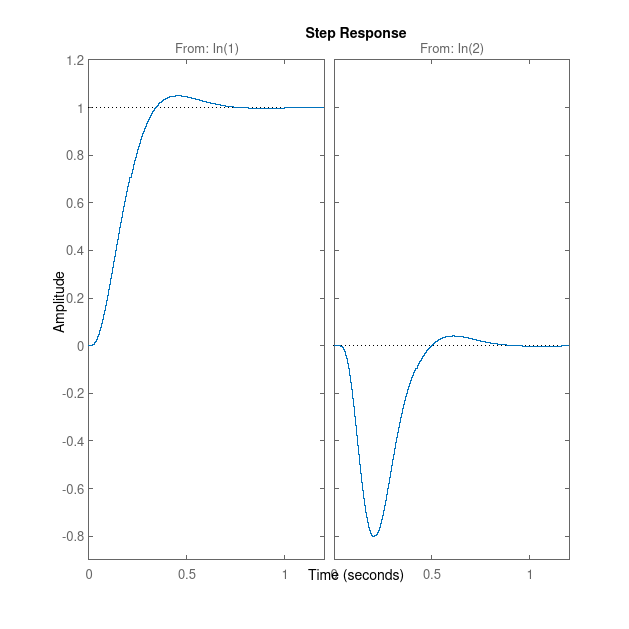

[F,prec] = place(sysDT.A,sysDT.B,zPoles);
A = sysDT.A; B = sysDT.B; C = sysDT.C; D = sysDT.D;

sysDTcl = ss(sysDT.A-sysDT.B*F,sysDT.B,sysDT.C,sysDT.D,Ts);
sysDTclFF = sysDTcl;
G = dcgain(sysDTclFF)^-1;

Acl = [ A      -B*F     -B;
        L*C A-L*C-B*F zeros(4,1);
        Li*C       -Li*C   1];
Bcl = [ B*G   B;
       B*G zeros(4,1);
        0   0];
Ccl = [0 0 200 1E6 0 0 0 0 0];

Dcl = [0];

sysPpObsFF = ss(Acl,Bcl,Ccl,Dcl,Ts);

figure('Position',[0 0 1000 1000])
step(sysPpObsFF)